clear;
clc;

numRx = 4;
numADCSamples = 200;
filestr = './move.bin'; 
  
data = read1843Data(filestr, numADCSamples, numRx);

numFrame = 500;
numChirp = size(data,2)/numADCSamples;
numChirpPerFrame = numChirp/numFrame; 

targRx = 1;
targData = data(targRx,:);
targData = reshape(targData, numADCSamples, []);

rangeWin = hamming(numADCSamples);
rangeResult = targData .* repmat(rangeWin, 1, size(targData,2));
rangeResult = fftshift(fft(rangeResult),1);

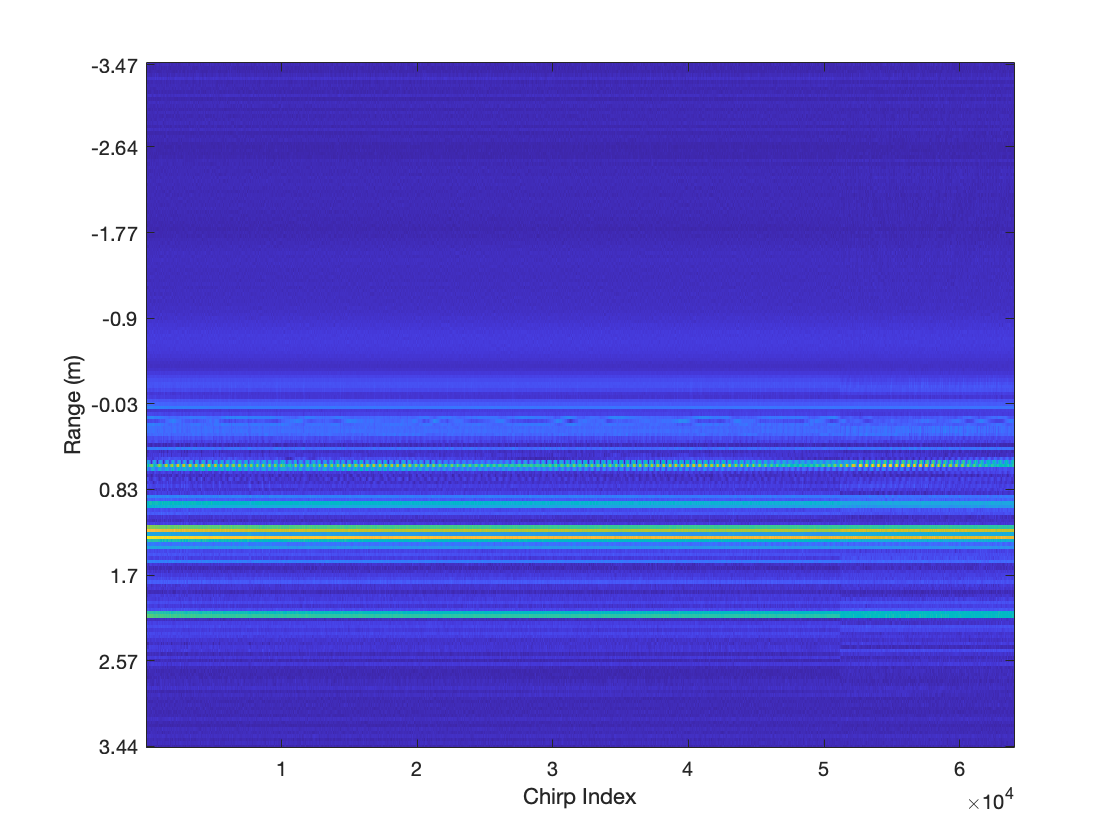

c = 3e8;
S = 54e12;
fs = 2500e3;

rangeRes = (c*fs) / (2*S*numADCSamples);
rangeTicks = rangeRes .* ((-numADCSamples/2):(numADCSamples/2-1));
rangeTicks = round(rangeTicks,2);

figure(1);
imagesc(abs(rangeResult));

yidxs = floor(linspace(1,length(rangeTicks),9));
yticks(yidxs);
yticklabels(string(rangeTicks(yidxs)))
xlabel('Chirp Index');
ylabel('Range (m)');

targFrame = 100;

dopplerWin = hamming(numChirpPerFrame).';
dopplerResult = rangeResult(:,(targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));
dopplerResult = dopplerResult .* repmat(dopplerWin, numADCSamples, 1);
dopplerResult = fftshift(fft(dopplerResult, numChirpPerFrame, 2),2);

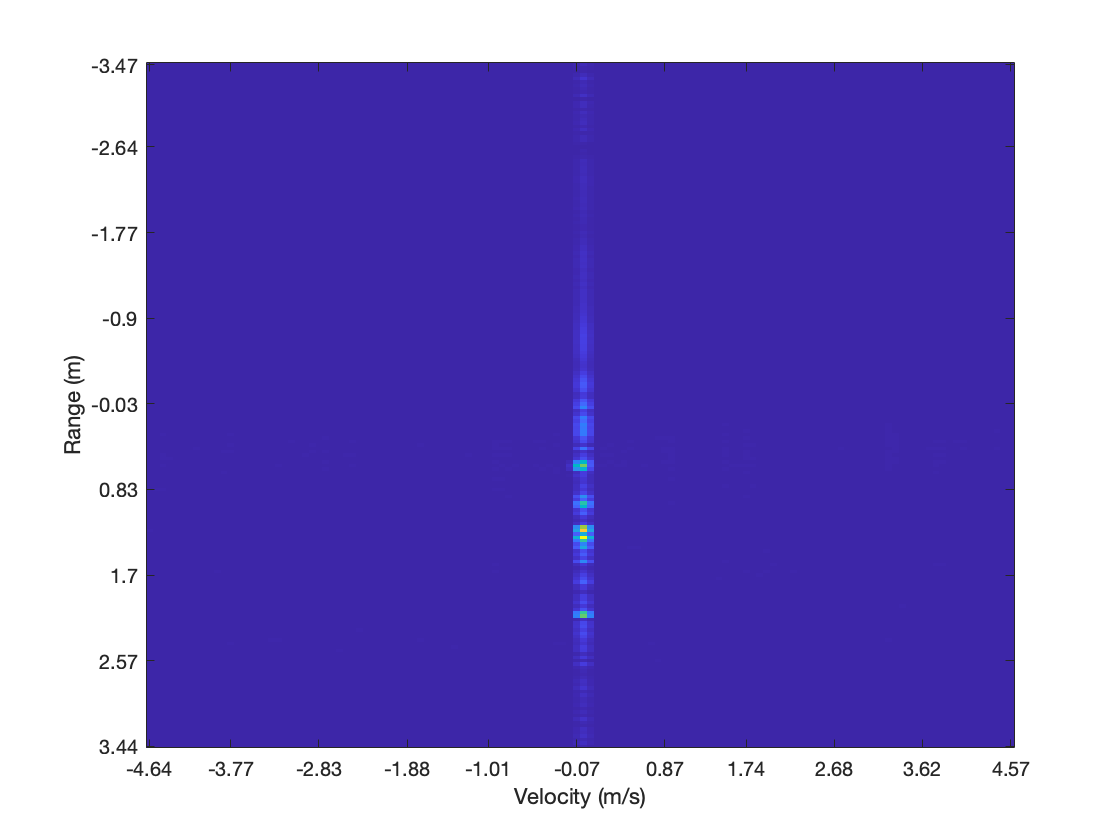

fc = 77e9;
Tc = 210e-6;
lambda = c / fc;

vecRes = lambda / (2*numChirpPerFrame*Tc);
vecTicks = vecRes .* ((-numChirpPerFrame/2):(numChirpPerFrame/2-1));
vecTicks = round(vecTicks, 2);

figure(2);
imagesc(abs(dopplerResult));
xidxs = floor(linspace(1,length(vecTicks),11));
yticks(yidxs);
yticklabels(string(rangeTicks(yidxs)))
xticks(xidxs);
xticklabels(string(vecTicks(xidxs)))
xlabel('Velocity (m/s)');
ylabel('Range (m)');

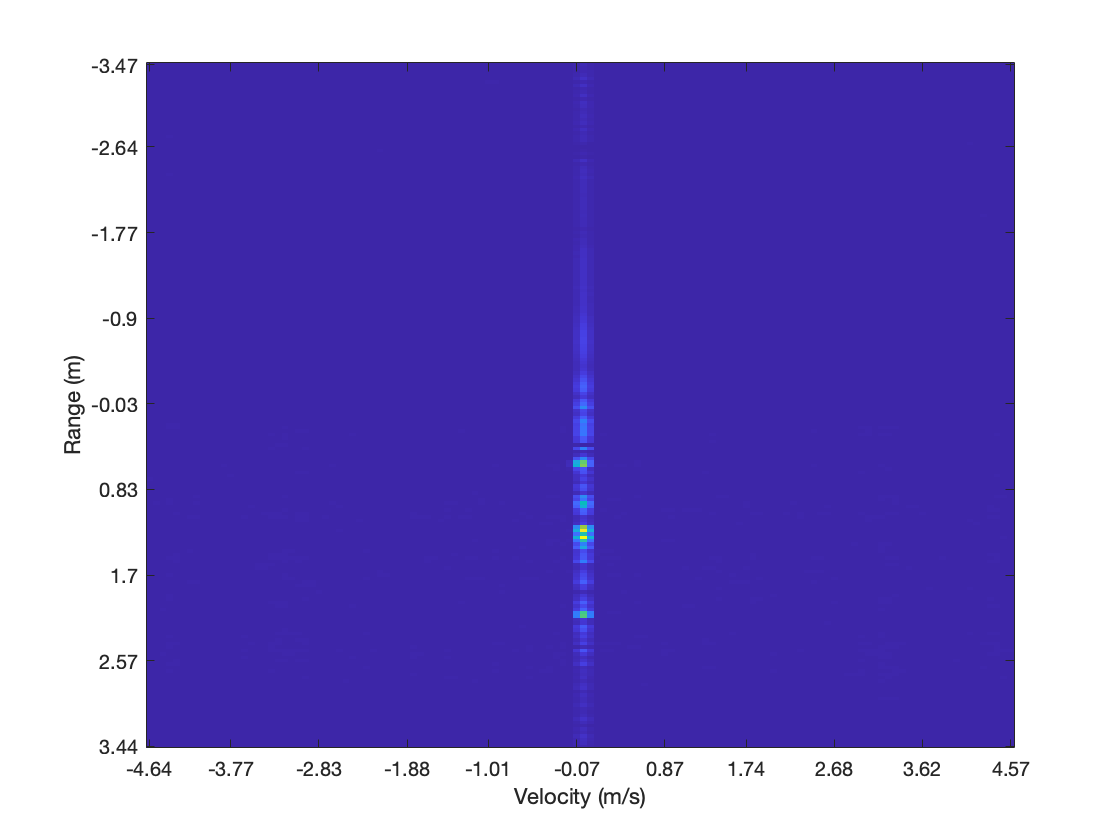

for targFrame = 1:numFrame
    targSeg = rangeResult(:, (targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));

    RDResult = targSeg .* repmat(dopplerWin, numADCSamples, 1);
    RDResult = fftshift(fft(RDResult, numChirpPerFrame, 2),2);

    figure(3);
    imagesc(abs(RDResult));
    xidxs = floor(linspace(1,length(vecTicks),11));
    yticks(yidxs);
    yticklabels(string(rangeTicks(yidxs)))
    xticks(xidxs);
    xticklabels(string(vecTicks(xidxs)))
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
    pause(0.1);
end

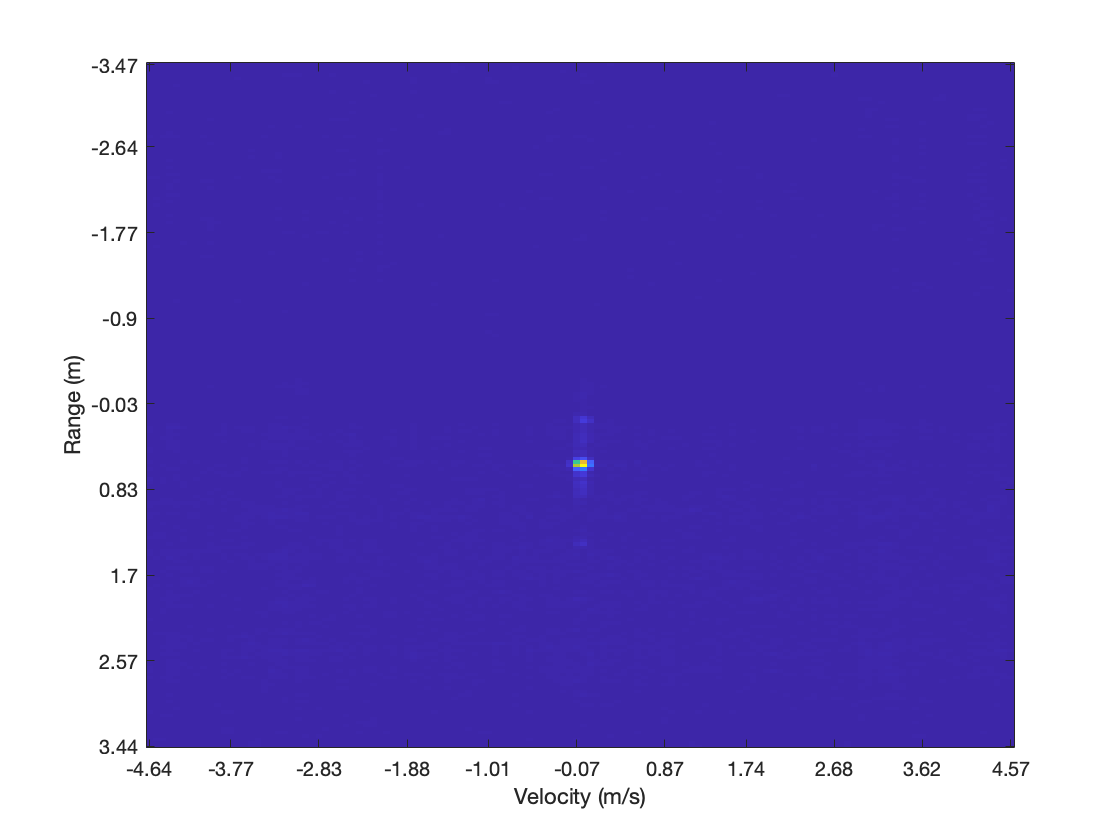

cycWin = 3*numADCSamples;
dymData = targData - smoothdata(targData, 2, 'movmean', cycWin);

for targFrame = 1:numFrame
    targSeg = dymData(:, (targFrame-1)*numChirpPerFrame+(1:numChirpPerFrame));

    RDResult = targSeg .* repmat(rangeWin, 1, numChirpPerFrame);
    RDResult = fftshift(fft(RDResult),1);
    
    RDResult = RDResult .* repmat(dopplerWin, numADCSamples, 1);
    RDResult = fftshift(fft(RDResult, numChirpPerFrame, 2),2);

    figure(4);
    imagesc(abs(RDResult));
    xidxs = floor(linspace(1,length(vecTicks),11));
    yticks(yidxs);
    yticklabels(string(rangeTicks(yidxs)))
    xticks(xidxs);
    xticklabels(string(vecTicks(xidxs)))
    xlabel('Velocity (m/s)');
    ylabel('Range (m)');
    pause(0.1);
end

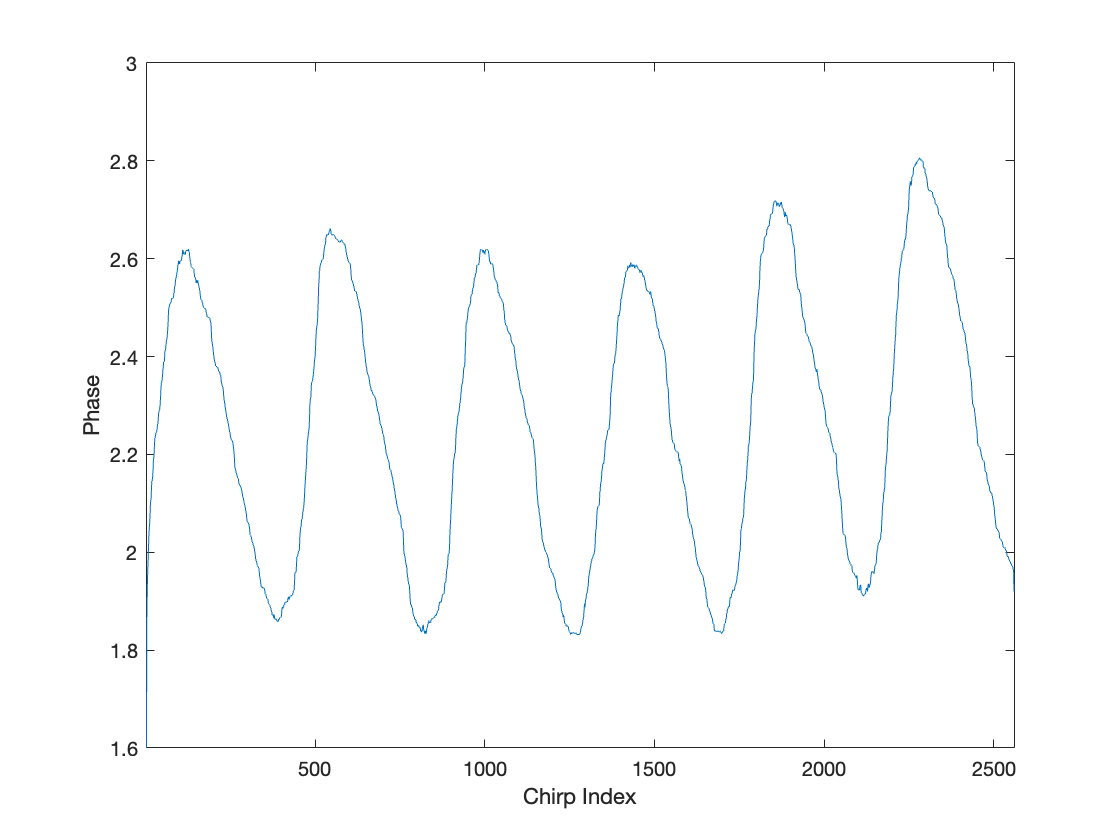

[~, MXIdx] = max(abs(rangeResult));
MXIdx = mode(MXIdx);

targFrame = 300;
segFrame = 20;
targBin = targData(MXIdx, (targFrame-1)*numChirpPerFrame+(1:segFrame*numChirpPerFrame));
targPhase = unwrap(angle(targBin));

[b,a] = butter(6,0.8);
filteredPhase = medfilt1(filter(b,a,targPhase),40);

figure(5);
plot(filteredPhase);
xlabel('Chirp Index');
ylabel('Phase');
xlim([1, size(targPhase,2)])
ylim([1.6, 3.0]);

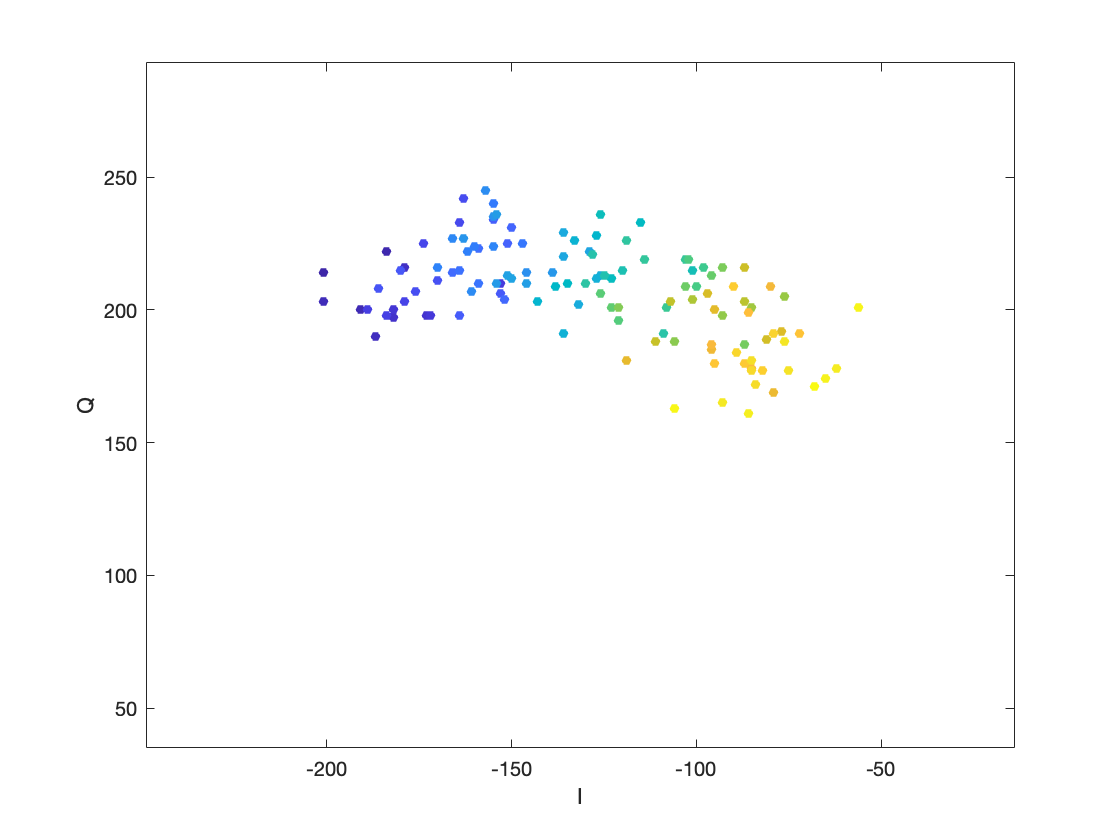

targReal = real(targBin);
targImag = imag(targBin);
plotColor = linspace(1,10,size(targBin,2));

stepNum = numChirpPerFrame;
for targFrame = 1:stepNum:size(targBin,2)
    figure(6), hold on; 

    scatter(targReal(targFrame+(0:stepNum-1)), ...
        targImag(targFrame+(0:stepNum-1)), ...
        25,plotColor(targFrame+(0:stepNum-1)), 'filled');

    box on;
    xlabel('I');
    ylabel('Q');
    xlim([min(targReal), max(targReal)]);
    ylim([min(targImag), max(targImag)]);
    pause(0.05);

    if mod(targFrame,3*stepNum) == 1
        clf;
        figure(6);

        box on;
        xlabel('I');
        ylabel('Q');
        xlim([min(targReal), max(targReal)]);
        ylim([min(targImag), max(targImag)]);
        pause(0.1);
    end
end